# Color Trajectory Plot

This plot is a method for showing a 2D trajectory (a list of x and y coordinates), along with an associated color for each data point.

## Generate example data

[x,y,c] = randomWalk;
whos x y c

  Name          Size             Bytes  Class     Attributes

  c         20000x1             160000  double              
  x         20000x1             160000  double              
  y         20000x1             160000  double              



## Plot the 2D trajectory

If no color data is provided, the chart uses the index of each coordinate to dictate the color of that coordinate.

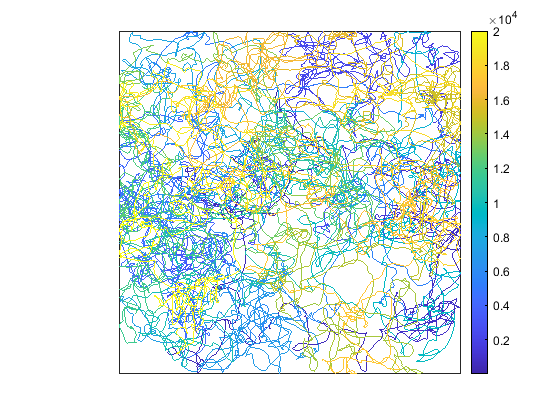

colorTrajectoryPlot(x,y)

## Changing the Colormap

Leveraging that behavior, you can switch the colormap to a two color colormap and use that to distinguish between the first and second half of the trajectory.

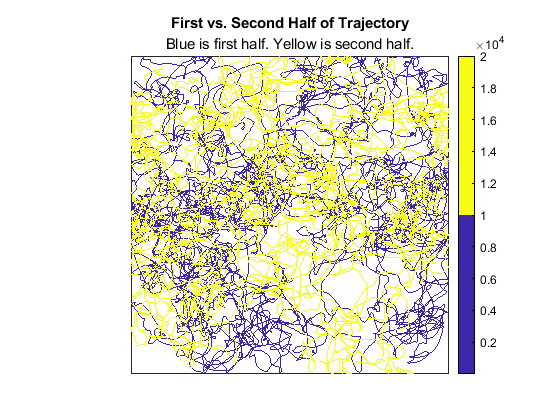

colormap(parula(2))
title('First vs. Second Half of Trajectory', 'Blue is first half. Yellow is second half.')

## Specifying Color Data

If you specify the color data, the color of each coordinate is determind by the corresponding value from the color data.

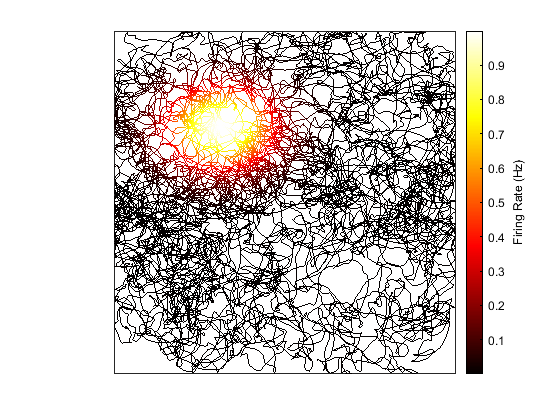

c = colorTrajectoryPlot(x,y,c);
c.ColorbarLabel = "Firing Rate (Hz)";
colormap(hot(256))